%%------------------------------------------------------------------
% Dynamic CFAR Simulation
% Geoffrey Dolinger, Brian Sun, Alex Stringer
%%------------------------------------------------------------------
%%------------------------------------------------------------------
% Parameters and System setup
%%------------------------------------------------------------------
%Experiment Parameters----------------------------------------------
c_size = 2000;                                                          %clutter size
R_targets = [2.020e3 2.040e3,2.060e3,2.080e3]';                         %range vector
v_targets =[200 -60, -140,-500]';                                       %velocity vector
sigmas = [1, 1, 1, 2]';                                                 %signal strength
%Clutter Parameters--------------------------------------------------
Rng_span = [2000 2100];                                                 %Range span for clutter
V_mean = 0;                                                             %Normal mean for velocity distibution of clutter sources
V_std = 100;                                                            %Standard Dev for velocity distibution of clutter sources
scale_ctr = 1;                                                          %Normal mean for scale value of wibble dist
scale_std = .1;                                                         %Standard Dev for scale value of wibble dist
shape_ctr = .5;                                                         %Normal mean for shape value of wibble dist
shape_std = .02;                                                        %Standard Dev for shape value of wibble dist
dist_density = .8;                                                      %Density of wibble sources per m in Rng_span
samples_mean = 100;                                                     %Normal mean for num of samples in a clutter source
samples_std = 20;                                                       %Standard Dev for num of samples in a clutter source
sigma_power = 1;                                                       %Average power for the clutter distribution

[clutter_rng, clutter_vel, clutter_sig] = clutter_wbl(Rng_span, V_mean, V_std, scale_ctr,scale_std,...
    shape_ctr, shape_std, dist_density, samples_mean, samples_std, sigma_power);

R_targets = [R_targets;clutter_rng];
v_targets = [v_targets;clutter_vel];
sigmas = [sigmas;clutter_sig];

%Radar Parameters---------------------------------------------------
F0 = 1e9;                                                               %Carrier Frequency
c = 3e8;                                                                %speed of light
lambda = c/F0;                                                          %system wavelength
Pt = 50;                                                                %Transmit power

%Transmitter Parameters---------------------------------------------
TR = 200e-6;                                                            %PRI, time per pulse
PRF = 1/TR;                                                              %Pulse repition frequency
M = 128;                                                                %# of pulses
m = (0:(M-1))-M/2;                                                      % pulse vector centered at 0
B = 200e6;                                                              %Bandwidth of transmitter signal
Tx = 5e-6;                                                              %transmit time

Fs = 2*B;                                                               %Sampling Freq. (chose 2x)
Ts = 1/(Fs);                                                            %sampling interval

Lx = round(Tx/Ts);                                                      %# of points in transmitted LFM

%waveform parameters
G = 100;                                                                %system gain
phi = rand()*2*pi();                                                    %random phi offset
alpha = sqrt((G^2*lambda^2*sigmas)./((4*pi)^3*R_targets.^4))*exp(1j*phi);%scaling calculation alpha
gamma = B/Tx;                                                           %gamma for phase component of LFM

%System Limits-----------------------------------------------------
Rmin_sys = Tx/2*c                                                       %Minimum range for system

Rmin_sys = 750.0000

Rmax_sys = (TR-Tx)/2*c                                                  %Maximum range for system

Rmax_sys = 29250

vmin = -PRF/4*lambda                                                    %Minimum velocity for system

vmin = -375

vmax = PRF/4*lambda                                                     %Maximum velocity for system

vmax = 375


R_res = c/(2*B)                                                         %Range resolution

R_res = 0.7500

FD_res = 1/(M.*TR)                                                      %F_D_resolution assuming M

FD_res = 39.0625

v_res = FD_res*lambda/2                                                 %Velocity resolution assuming M

v_res = 5.8594


%Receiver Parameters-----------------------------------------------
Rmin = 2e3;                                                             %Selected minimum range
Rmax = 2.1e3;                                                           %Selected maximum range
t_i = 2*Rmin/c;                                                          %Corresponding minimum fast time minimum 
t_f = 2*Rmax/c+Tx;                                                       %Corresponding minimum fast time minimum

Range = R_targets - v_targets*m.*TR;                                    %matrix of range values per CPI
tau = 2*Range/c;                                                        %time delay of target return per CPI
F_D = 2*v_targets/lambda;                                               %Doppler frequency for each target

Nfft_Fd = 1024;                                                         %FFT sampling rate Doppler processing


%Noise Parameters
kB = 1.38e-23;                                                          %Boltzman constant
Temp = 290;                                                             %noise temperature
Fsys = 300;                                                               %system loss
Pn = kB*Temp*Fs*Fsys;                                                   %Calculated noise power

%%------------------------------------------------------------------
% Transmit signal simulation
%%------------------------------------------------------------------
x_amp = conv(hann(0.1*Lx), ones(Lx,1));                                 %hanning window for LFM
x_amp = x_amp/max(abs(x_amp))*sqrt(Pt);                                 %amplitude window given transmit power
Lx_new = length(x_amp);                                                 %new convolved length
Tx_new = Lx_new*Ts;                                                     %new convolved period
t_x = (0:Lx_new-1)*Ts;                                                  %transmit time scale given convolution
B_new = gamma*Tx_new;                                                   %New effective Bandwidth
x_phase = (-2.*pi.*(.5*B_new).*t_x + pi.*gamma*t_x.^2)';                %transmitted phase component of LFM
x_TX = (x_amp.*exp(1j.*x_phase));                                       %Transmitted signal

%Noise Generation --------------------------------------------------
t_fast =(t_i:Ts:t_f);                                                   %Fast time vector                               
L_ADC = length(t_fast);
noise = sqrt(Pn/2)*((randn(L_ADC,M)) + 1j*randn(L_ADC,M));


%%------------------------------------------------------------------
% Receive signal simulation Range/Doppler shift
%%------------------------------------------------------------------
%Time Shift---------------------------------------------------------
                                                 %Received signal samples
X_TX_f = fftshift(fft(x_TX,L_ADC));                                     %Freq domanin transmitted signal
F = -Fs/2 + (0:(L_ADC-1))'*Fs/L_ADC;                                    %Frequency domain scale
x_RX_temp = zeros(L_ADC,M,size(R_targets,1));                           %Place holder for time shift

for i = 1:length(R_targets)                                             %Loop of all targets   
    X_RX_tshift = repmat(X_TX_f,1,M).*exp(-1j*2*pi*F*(tau(i,:)-t_i));   %Time shift in Freq domain
    %Doppler Shift------------------------------------------------------
    X_RX_F = X_RX_tshift.*alpha(i).*repmat(exp(1j*2*pi*F_D(i)*m*TR),L_ADC,1); %Doppler shift and alpha scaling
    x_RX = ifft(ifftshift(X_RX_F,1),L_ADC,1);                           % Convert back to time domain
    x_RX_temp(:,:,i) = x_RX;                                            %Store values for this target
end

x_RX_TDshift = sum(x_RX_temp,3)+noise;                                  %Sum all target to get recieved signal
X_RX = fftshift(fft(x_RX_TDshift,L_ADC,1),1);                           %Freq. domain recieved signal


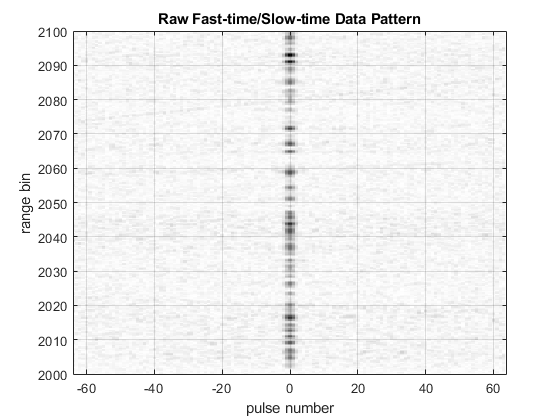

%%------------------------------------------------------------------
% Matched Filter
%%------------------------------------------------------------------
Y_m = (repmat(conj(X_TX_f),1,M).*X_RX);                                 %Matched milter with impulse response
y_m = ifft(ifftshift(Y_m,1),L_ADC,1);                                   %Matched filter results time domain
R_axis = c*t_fast/2;                                                    %Range axis
figure                                                                  %Plot matched filter given CPI pulses                   
imagesc(m,R_axis,abs(y_m))
grid
colormap(flipud(gray))
set(gca,'ydir','normal')
xlabel('pulse number')
ylabel('range bin')
title('Raw Fast-time/Slow-time Data Pattern')
axis([-M/2 M/2 Rmin Rmax])

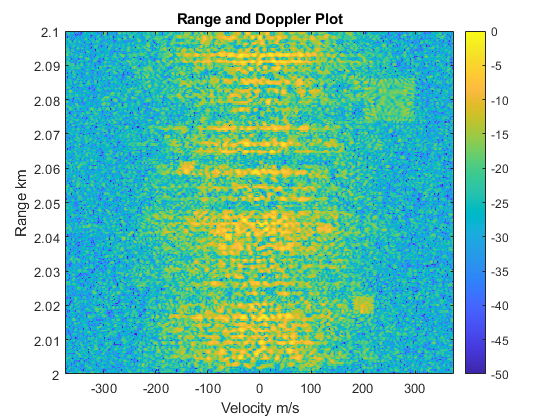

%%------------------------------------------------------------------
% Doppler Processing
%%------------------------------------------------------------------
RD_processed = fft(Y_m,Nfft_Fd,2);                                      %FFT Doppler processing
RD_processed = ifft(RD_processed);                                      %Return to time domain 
RD_Norm = fftshift(RD_processed,2);                                     %Doppler processing shifted
Fd_axis = -PRF/2 + (0:(Nfft_Fd-1))'*PRF/Nfft_Fd;                        %Doppler freq. axis
V_axis = Fd_axis/2*lambda;                                              %Velocity axis

figure                                                                  %Range Doppler plot FTT Doppler processing
imagesc(V_axis,R_axis*1e-3,db(abs(RD_Norm)./max(max(abs(RD_Norm)))),[-50 0]);
title(sprintf('Range and Doppler Plot'))
xlabel('Velocity m/s')
ylabel('Range km')
axis([vmin vmax Rmin*1e-3 Rmax*1e-3])
set(gca,'ydir','normal')
colorbar

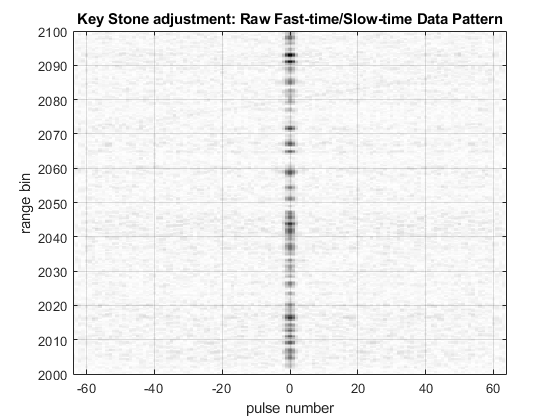

%%------------------------------------------------------------------
% Keystone
%%------------------------------------------------------------------
m_scaled = ((F0)./(F0+F))*m;                                            %Keystone frequency scaling matrix
Y_m_ks=sinc_interpolation(Y_m,m,m_scaled);                              %sinc interpolation function (see end)
y_m_ks = ifft(ifftshift(Y_m_ks,1),L_ADC,1);                             % Convert to time domain to see plot
figure                                                                  %Plot matched filter given CPI pulses (keystone)  
imagesc(m,R_axis,abs(y_m_ks))
grid
colormap(flipud(gray))
set(gca,'ydir','normal')
xlabel('pulse number')
ylabel('range bin')
title('Key Stone adjustment: Raw Fast-time/Slow-time Data Pattern')
axis([-M/2 M/2 Rmin Rmax])

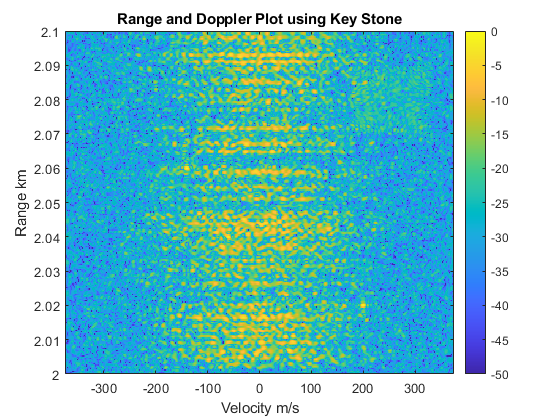


RD_processed_ks = fft(Y_m_ks,Nfft_Fd,2);                                 %FFT Doppler processing
RD_processed_ks = ifft(RD_processed_ks);                                 %Return to time domain
RD_Norm_ks = fftshift(RD_processed_ks,2);                                %Doppler processing shifted
figure                                                                   %Range Doppler plot FTT Doppler processing (keystone)
imagesc(V_axis,R_axis*1e-3,db(abs(RD_Norm_ks)./max(max(abs(RD_Norm_ks)))),[-50 0]);
title(sprintf('Range and Doppler Plot using Key Stone'))
xlabel('Velocity m/s')
ylabel('Range km')
axis([vmin vmax Rmin*1e-3 Rmax*1e-3])
set(gca,'ydir','normal')
colorbar

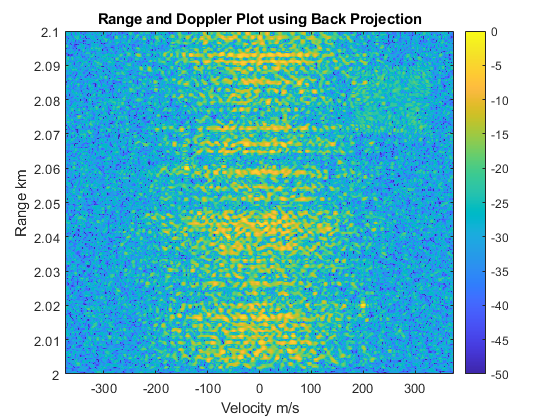

%%------------------------------------------------------------------
% Backprojection
%%------------------------------------------------------------------
Upsample = 12;                                                           %Upsampling rate
UL_ADC = Upsample*L_ADC;                                                %Upsampled # of samples                        
RDM = zeros(L_ADC,Nfft_Fd);                                             %Empty matrix to hold RD-map
T_sU =(t_f-t_i)/(UL_ADC-1);                                             %upsampled sampling interval 
t_fastU = (t_i:T_sU:t_f);                                               %Upsampled time scale                                               
R_axisU = c*t_fastU/2;                                                  %Upsampled range axis
for i = 1:M                                                             %loop across M
    R_delta = R_axis'-(V_axis'.*m(i).*TR);                              %calculated motion profile for this slice
    Y_Um = zeros(UL_ADC,1);                                             %empty upsampled vector for zero padding
    Y_m_bp = ifftshift(Y_m(:,i));
    Y_Um(1:round(L_ADC/2),1) = Y_m_bp(1:round(L_ADC/2));                %Insert front half 
    Y_Um(length(Y_Um)-round(L_ADC/2):end,1)=Y_m_bp(L_ADC-round(L_ADC/2):end);%Insert back half
    y_Um=ifft(Y_Um,UL_ADC);                                             %Convert back to time domain
    RDM_add = interp1(R_axisU',y_Um,R_delta,'linear',0);                %Linear interpolation for energy at that pixil
    RDM_add_pc = RDM_add.*exp(1j*4*pi*F0*R_delta./c);                   %Phase shift energy at pixil
    RDM = RDM+RDM_add_pc;                                               %add to RD-map for this slice
end
figure                                                                  %Plot range-Doppler map for backprojection
imagesc(V_axis,R_axis*1e-3,db(abs(RDM)./max(max(abs(RDM)))),[-50 0]);
title(sprintf('Range and Doppler Plot using Back Projection'))
xlabel('Velocity m/s')
ylabel('Range km')
axis([vmin vmax Rmin*1e-3 Rmax*1e-3])
set(gca,'ydir','normal')
colorbar

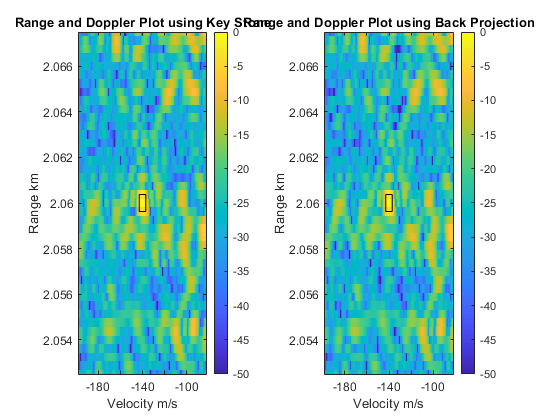

target =3;
zoom = 10;

figure                                                                   %Range Doppler plot FTT Doppler processing (keystone)
subplot(1,2,1)
imagesc(V_axis,R_axis*1e-3,db(abs(RD_Norm_ks)./max(max(abs(RD_Norm_ks)))),[-50 0]);
title(sprintf('Range and Doppler Plot using Key Stone'))
xlabel('Velocity m/s')
ylabel('Range km')
axis([(v_targets(target)-zoom*v_res) (v_targets(target)+zoom*v_res) (R_targets(target)-zoom*R_res)*1e-3 (R_targets(target)+zoom*R_res)*1e-3])
set(gca,'ydir','normal')
colorbar
hold on;
rectangle('Position',[v_targets(target)-v_res/2,(R_targets(target)-R_res/2)*1e-3,v_res,(R_res)*1e-3])

subplot(1,2,2)
imagesc(V_axis,R_axis*1e-3,db(abs(RDM)./max(max(abs(RDM)))),[-50 0]);
title(sprintf('Range and Doppler Plot using Back Projection'))
xlabel('Velocity m/s')
ylabel('Range km')
axis([(v_targets(target)-zoom*v_res) (v_targets(target)+zoom*v_res) (R_targets(target)-zoom*R_res)*1e-3 (R_targets(target)+zoom*R_res)*1e-3])
set(gca,'ydir','normal')
colorbar
hold on;
rectangle('Position',[v_targets(target)-v_res/2,(R_targets(target)-R_res/2)*1e-3,v_res,(R_res)*1e-3])

cfar =   phased.CFARDetector2D with properties:

                   Method: 'CA'
            GuardBandSize: 5
         TrainingBandSize: 10
          ThresholdFactor: 'Auto'
    ProbabilityFalseAlarm: 0.0020
             OutputFormat: 'CUT result'
      ThresholdOutputPort: false
     NoisePowerOutputPort: false


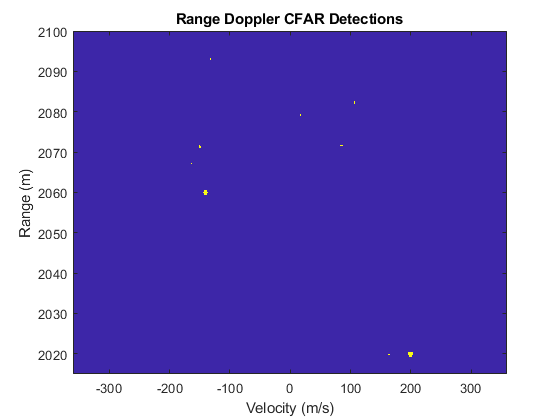

detections_ind = CA_CFAR(RDM, R_axis, V_axis, [2000 2100], [-375 375],5,10,2e-3, true); %Cell averaging CFAR

function [detections_ind] = CA_CFAR(RDM, R_axis, V_axis, R_window, V_window,Gband, Tband, PFA, plot)
    RDM_map = abs(RDM);                                                     %Ensure RDM is Real
    cfar = phased.CFARDetector2D('GuardBandSize',Gband,'TrainingBandSize',Tband,... %set-up CFAR Detector
      'ProbabilityFalseAlarm',PFA)
    R_window(1) = max(min(R_axis)+Tband+Gband,R_window(1));                 %Ensure CUTs are far enough from edge
    R_window(2) = min(max(R_axis)-Tband-Gband,R_window(2));
    V_window(1) = max(min(V_axis)+Tband+Gband,V_window(1));
    V_window(2) = min(max(V_axis)-Tband-Gband,V_window(2));
    [~,rangeIndx] = min(abs(R_axis'-R_window));                             %Calulate range of CUTs
    [~,dopplerIndx] = min(abs(V_axis-V_window));
    [columnInds,rowInds] = meshgrid(dopplerIndx(1):dopplerIndx(2),...       %create Mesh grid for all CUTs locations
      rangeIndx(1):rangeIndx(2));
    CUTIdx = [rowInds(:) columnInds(:)]';                                   %Create CUTs index list
    detections = cfar(RDM_map,CUTIdx);                                      %Preform CA-CFAR and return detection locations
    detections_ind = CUTIdx(:,detections==1);                               %List detection index pairs
    if plot                                                                 %If plot flag is true, plot detection map
        helperDetectionsMap(RDM_map,R_axis',V_axis,rangeIndx,dopplerIndx,detections)
        xlim(V_window)
        ylim(R_window)
        xlabel('Velocity (m/s)')
    end
end

function [interp_data] = sinc_interpolation(data,m,m_scaled)                %Sinc interpolation function
    
    interp_data = zeros(size(data));   
    for iF = 1:size(data,1)                                                 %implemented as double loop, upgrade to single loop with mask. 
        for im = 1:size(m,2)
            if and(m_scaled(iF,im)<max(m),m_scaled(iF,im)>min(m))           %If points are in range, sum sinc functions           
                interp_data(iF,im) = sum(data(iF,:).*sinc((m_scaled(iF,im)-m))); 
            else                                                            %If not in range set to 0
                interp_data(iF,im) = 0;
            end
        end
    end
end

function [Range,Velocity,Sigma] = clutter_wbl(Rng_span, V_mean, V_std, scale_ctr,scale_std,...
    shape_ctr, shape_std, dist_density, samples_mean, samples_std, sigma_power)
    
    dist_num = round((Rng_span(2)-Rng_span(1)).*dist_density);              %
    source_centers = (Rng_span(2)-Rng_span(1))*rand(dist_num,1) + Rng_span(1);
    Range = [];
    Velocity = [];
    Sigma = [];
    for i = 1:dist_num
        samples = max(round(samples_std.*randn+samples_mean),0);
        scale = max(scale_std.*randn+scale_ctr,0);
        shape = max(shape_std.*randn+shape_ctr,0);
        Rng_wbl = source_centers(i)+wblrnd(scale, shape, samples,1);
        Range = [Range;Rng_wbl];
        vel_norm = V_std*randn(samples,1)+V_mean;
        Velocity = [Velocity;vel_norm];
        sigma_norm = max((sigma_power./(10*samples)).*randn(samples,1)+(sigma_power./samples),0);
        Sigma = [Sigma;sigma_norm];
    end
end